# Discrete Cosine Transform

### ### Agam Goyal ###

## Display Blocks 

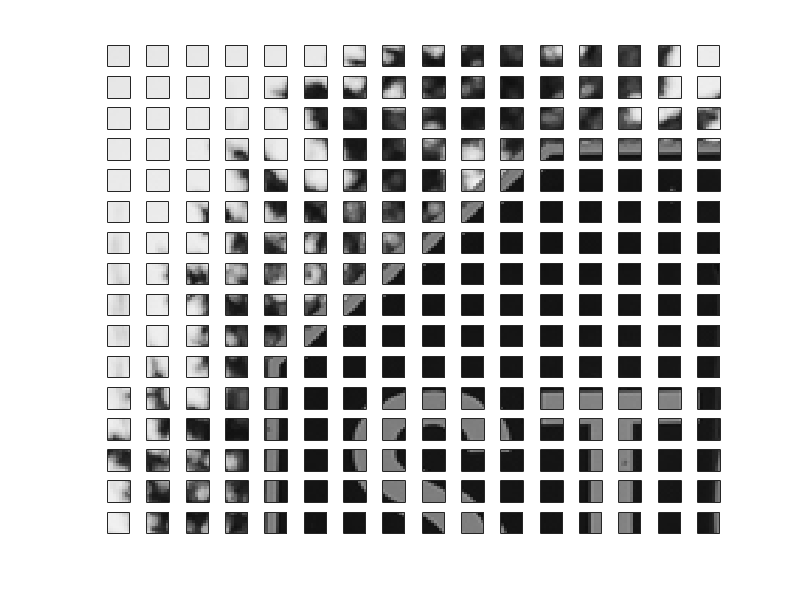

% Displays the upper left 128 by 128 pixels of an image as a matrix of
% sixteen by sixteen 8 by 8 blocks

%% Set up workspace
close all
clear

load stop.mat  % file containing image stop
im = stop;

[M,N] = size(im);

C_im = [0,255]; % maintain image dynamic range for all blocks

%% 

figure
for i=1:min(16, round(M/8))
    for j=1:min(16, round(N/8))
        nrange = (i-1)*8+1:(i-1)*8+8;
        mrange = (j-1)*8+1:(j-1)*8+8;
        block = im(nrange,mrange); 
        subplot(16,16,j+(i-1)*16)
        imagesc(block,C_im)
        colormap(gray)
        set(gca,'Xtick',[])
        set(gca,'Ytick',[])
        axis('square')
    end
end

## The (1,1) block

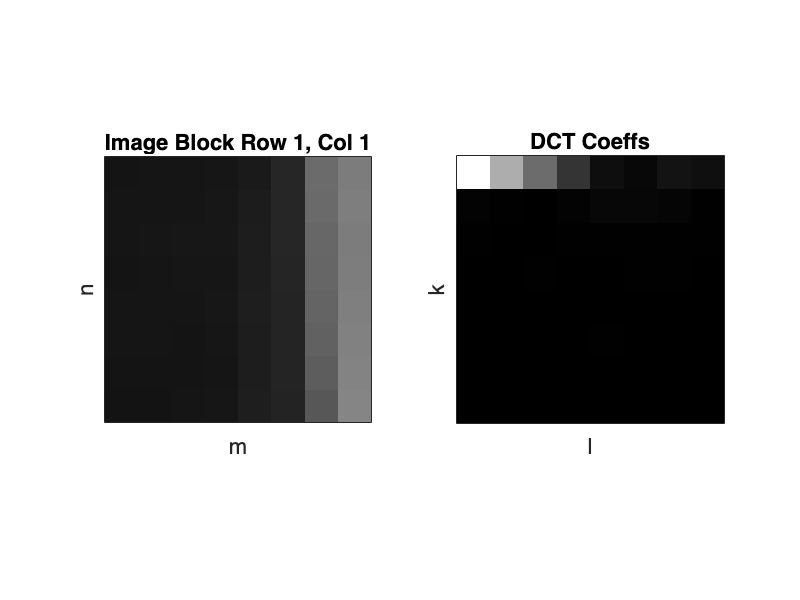

% Your code here
dct_coeff = DCTBlock(block, 1, 1);

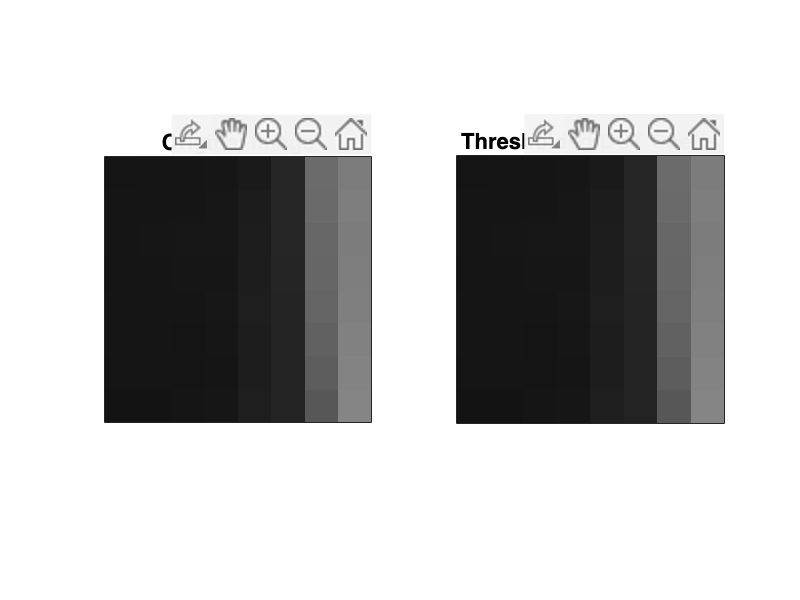

thresh_coeff =   376.7500 -254.9363  160.0994  -77.3466   20.7500   13.0325  -28.9728   22.8967
    5.0629   -2.1521    0.0828    5.0165  -11.2365   11.3126   -7.7839    2.7658
   -2.2304   -1.1267    1.1036   -1.8362    2.0391   -2.1277    2.8107   -1.9297
    0.1391   -1.3307    2.0631    1.2324   -1.0907    2.0606   -2.3088   -0.1130
   -1.2500    0.0949   -0.9239   -0.8486    0.2500   -0.2663    0.3827    0.2738
   -1.0217    0.0879    0.1720    0.5429   -2.0409    0.2853    0.0287    0.2195
   -0.1585    1.3860   -0.6893   -0.2192   -0.3034   -0.2894    0.3964   -0.2357
    0.4226    0.7480   -0.5353    0.1372   -0.1031    0.0416   -0.0211    0.1344


thresh_coeff = DCT_Thresh(dct_coeff, 0.01)

## The (8,3) block

% Your code here







## The (15,13) block

% Your code here






